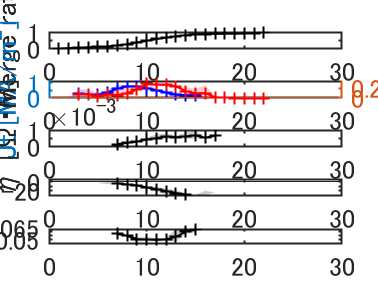

%2022/10/11更新
clearvars 
%グループ分けした合体速度とシート傾き・シート幅の比較
%グループ分けしたシート幅の比較
pathname.ts3u=getenv('ts3u_path');%old-koalaのts-3uまでのパス
pathname.fourier=getenv('fourier_path');%md0までのpath
pathname.NIFS=getenv('NIFS_path');%resultsまでのpath

% DOCID='1wG5fBaiQ7-jOzOI-2pkPAeV6SDiHc_LrOdcbWlvhHBw';
% T=getTS6log(DOCID);% ログのテーブルを取得

start=460;
frame=50;
elapsedtime=1:frame;
trange=[1:frame]+start;

IDXlist=[2911:2913 2925 2926 2927 2931 2933];
tstartlist=[472 472 472 477 477 477 482 482];
tendlist=[482 482 482 487 487 487 500 500];
tstartlist=tstartlist-start;
tendlist=tendlist-start;

%fitrate, sheeet angle
load('C:\Users\kuru1\OneDrive - g.ecc.u-tokyo.ac.jp\labo\220801中間審査\data\fitrate.mat');

%sheet wide(delta)
load('C:\Users\kuru1\OneDrive - g.ecc.u-tokyo.ac.jp\labo\220801中間審査\data\a_wide_Br.mat');
% wide(4,1)=NaN;
a_wide=fillmissing(wide,'previous');
a_wide(end-1:end,:)=NaN;
% a_wide=wide;%0.5.*fillmissing(wide,'previous');%NaNは前の値で埋める
load('C:\Users\kuru1\OneDrive - g.ecc.u-tokyo.ac.jp\labo\220801中間審査\data\b_wide_Br.mat');
b_wide=fillmissing(wide,'previous');
b_wide(end-1:end,:)=NaN;
% b_wide=wide;%0.5.*fillmissing(wide,'previous');
load('C:\Users\kuru1\OneDrive - g.ecc.u-tokyo.ac.jp\labo\220801中間審査\data\c_wide_Br.mat');
c_wide=fillmissing(wide,'previous');
c_wide(end-5:end,:)=NaN;
% c_wide=wide;%0.5.*fillmissing(wide,'previous');
clear wide
%memo
%(abc)_wide.mat:中間審査前の計算・midplaneの垂線上のJtは近接するr座標二点での平均・Jtの半値全幅はmin(Jt)*0.5より小さい中で一番近いz座標
%(abc)_wide_poly.mat:8/10の計算・midplaneの垂線上のJtは近接するr座標二点での内分・Jtの半値全幅はpolyxpolyでの交点
%(abc)_wide_fw.mat:8/18の計算・midplaneの垂線上のJtは近接するr座標二点での内分・Jtの全値幅（Jt=0点）はpolyxpolyでの交点
%(abc)_wide_fw04.mat:9/6の計算・midplaneの垂線上のJtは近接するr座標二点での内分・Jtの全値幅（Jt=-1e+5点）はpolyxpolyでの交点
%(abc)_wide_Br.mat:9/26の計算・midplaneの垂線上のBrの極大・極小点の間の間隔

%xpointでの抵抗
load('C:\Users\kuru1\OneDrive - g.ecc.u-tokyo.ac.jp\labo\220801中間審査\data\xpoint.mat','xeta');
xeta=-1.*xeta;
xeta(isnan(slope))=NaN;

%xpointでのJt,Et,Resistivity(CAO-probe)
%start=460, frame=50
%IDXlist=[2911:2913 2925 2926 2927 2931 2933 2947:2950 2942 2943 2946];
load('C:\Users\kuru1\OneDrive - g.ecc.u-tokyo.ac.jp\labo\220801中間審査\data\caoxpoint.mat');
caoJt=-1.*1e-6.*caoJt; %Jt at Xpoint [MA/m^{2}]
caoEt=-1.*1e-3.*caoEt; %Et at Xpoint [kV/m]
caoJt(:,9:end)=[];
caoEt(:,9:end)=[];
caoRes(:,9:end)=[];
% caoJt(isnan(slope))=NaN;
% caoEt(isnan(slope))=NaN;
% caoRes(isnan(slope))=NaN;

wide=zeros(frame,numel(IDXlist));
i=1:3;
wide(tstartlist(1,i):tendlist(i),i)=a_wide(:,i);
i=4:6;
wide(tstartlist(1,i):tendlist(i),i)=b_wide(:,i-3);
i=7:8;
wide(tstartlist(1,i):tendlist(i),i)=c_wide(:,i-6);
clear i
wide(isnan(slope))=NaN;

i=1:3;
awide(:,i)=wide(merge_ind(1,i):merge_ind(1,i)+a_frame,i);
aeta(:,i)=xeta(merge_ind(1,i):merge_ind(1,i)+a_frame,i);
acaoJt(:,i)=caoJt(merge_ind(1,i):merge_ind(1,i)+a_frame,i);
acaoEt(:,i)=caoEt(merge_ind(1,i):merge_ind(1,i)+a_frame,i);
i=4:6;
bwide(:,i-3)=wide(merge_ind(1,i):merge_ind(1,i)+b_frame,i);
beta(:,i-3)=xeta(merge_ind(1,i):merge_ind(1,i)+b_frame,i);
bcaoJt(:,i-3)=caoJt(merge_ind(1,i):merge_ind(1,i)+b_frame,i);
bcaoEt(:,i-3)=caoEt(merge_ind(1,i):merge_ind(1,i)+b_frame,i);
i=7:8;
cwide(:,i-6)=wide(merge_ind(1,i):merge_ind(1,i)+c_frame,i);
ceta(:,i-6)=xeta(merge_ind(1,i):merge_ind(1,i)+c_frame,i);
ccaoJt(:,i-6)=caoJt(merge_ind(1,i):merge_ind(1,i)+c_frame,i);
ccaoEt(:,i-6)=caoEt(merge_ind(1,i):merge_ind(1,i)+c_frame,i);
clear i

%(a)のみ
figure
% f1=figure;
% f1.WindowState='maximized';
subplot(5,1,1)
plot(arange,mean(afit(:,1:3),2),'k-+','LineWidth',1)
hold on
 ar1 = area(arange,[max(afit(:,1:3),[],2), min(afit(:,1:3),[],2)-max(afit(:,1:3),[],2)]);
set(ar1(1),'FaceColor','None','LineStyle','None')
set(ar1(2),'FaceColor','k','FaceAlpha',0.2,'LineStyle','None')
hold off
ylabel('Merge ratio')
xlim([0 30])
ylim([0 1])
ha1 = gca;
ha1.LineWidth = 1;
ha1.FontSize=13;

subplot(5,1,2)
yyaxis left
plot(arange,mean(acaoJt(:,1:3),2),'b-+','LineWidth',1)
hold on
 ar1 = area(arange,[max(acaoJt(:,1:3),[],2), min(acaoJt(:,1:3),[],2)-max(acaoJt(:,1:3),[],2)]);
set(ar1(1),'FaceColor','None','LineStyle','None')
set(ar1(2),'FaceColor','b','FaceAlpha',0.2,'LineStyle','None')
hold off
ylabel('Jt [MA/m^{2}]')
xlim([0 30])
ylim([0 1.1])
yyaxis right
plot(arange,mean(acaoEt(:,1:3),2),'r-+','LineWidth',1)
hold on
 ar2 = area(arange,[max(acaoEt(:,1:3),[],2), min(acaoEt(:,1:3),[],2)-max(acaoEt(:,1:3),[],2)]);
set(ar2(1),'FaceColor','None','LineStyle','None')
set(ar2(2),'FaceColor','r','FaceAlpha',0.2,'LineStyle','None')
hold off
ylabel('Et [kV/m]')
xlim([0 30])
ylim([0 0.35])
ha2 = gca;
ha2.LineWidth = 1;
ha2.FontSize=13;

subplot(5,1,3)
plot(arange,mean(aeta(:,1:3),2),'k-+','LineWidth',1)
hold on
 ar1 = area(arange,[max(aeta(:,1:3),[],2), min(aeta(:,1:3),[],2)-max(aeta(:,1:3),[],2)]);
set(ar1(1),'FaceColor','None','LineStyle','None')
set(ar1(2),'FaceColor','k','FaceAlpha',0.2,'LineStyle','None')
hold off
ylabel('η [Ω・m]')
xlim([0 30])
ha3 = gca;
ha3.LineWidth = 1;
ha3.FontSize=13;

subplot(5,1,4)
plot(arange,mean(aslope(:,1:3),2),'k-+','LineWidth',1)
hold on
 ar1 = area(arange,[max(aslope(:,1:3),[],2), min(aslope(:,1:3),[],2)-max(aslope(:,1:3),[],2)]);
set(ar1(1),'FaceColor','None','LineStyle','None')
set(ar1(2),'FaceColor','k','FaceAlpha',0.2,'LineStyle','None')
hold off
ylabel('angle [°]')
xlim([0 30])
ylim([-0.55 0.1].*180./pi)
ha4 = gca;
ha4.LineWidth = 1;
ha4.FontSize=13;

subplot(5,1,5)
plot(arange,mean(awide(:,1:3),2),'k-+','LineWidth',1)
hold on
 ar1 = area(arange,[max(awide(:,1:3),[],2), min(awide(:,1:3),[],2)-max(awide(:,1:3),[],2)]);
set(ar1(1),'FaceColor','None','LineStyle','None')
set(ar1(2),'FaceColor','k','FaceAlpha',0.2,'LineStyle','None')
hold off
ylabel('δ [m]')
xlabel('Time [us]')
xlim([0 30])
ylim([0.045 0.065])%ylim([0.01 0.045])
ha5 = gca;
ha5.LineWidth = 1;
ha5.FontSize=13;

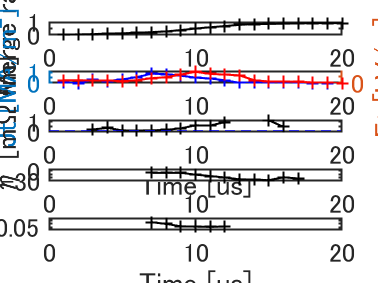


%(a)2911のみ
figure
% f1=figure;
% f1.WindowState='maximized';
subplot(5,1,1)
plot(arange,mean(afit(:,1:1),2),'k-+','LineWidth',1)
ylabel('Merge ratio')
xlim([0 20])%xlim([0 30])
ylim([0 1])
ha1 = gca;
ha1.LineWidth = 1;
ha1.FontSize=13;

subplot(5,1,2)
yyaxis left
plot(arange,mean(acaoJt(:,1:1),2),'b-+','LineWidth',1)
ylabel('Jt [MA/m^{2}]')
xlim([0 20])%xlim([0 30])
ylim([0 1.1])
yyaxis right
plot(arange,mean(acaoEt(:,1:1),2),'r-+','LineWidth',1)
ylabel('Et [kV/m]')
xlim([0 20])%xlim([0 30])
ylim([0 0.35])
ha2 = gca;
ha2.LineWidth = 1;
ha2.FontSize=13;

subplot(5,1,3)
%2022/11/25：X点E/jでt=1-6us追加
aeta_all=acaoEt(:,1)./acaoJt(:,1);
aeta_all(1:2)=NaN;
aeta_all(17:end)=NaN;
% aeta_all(7:17)=aeta(7:17,1:1).*1e+3;
plot(arange,aeta_all,'k-+','LineWidth',1)
% plot(arange,mean(aeta(:,1:1),2).*1e+3,'k-+','LineWidth',1)
hold on
yline(0.1,'b--')%古典抵抗
hold off
ylabel('η [mΩ・m]')
xlabel('Time [us]')
xlim([0 20])%xlim([0 30])
ylim([0 1.2])%ylim([0 1.1])
ha3 = gca;
ha3.LineWidth = 1;
ha3.FontSize=13;

subplot(5,1,4)
plot(arange,mean(aslope(:,1:1),2),'k-+','LineWidth',1)
ylabel('angle [°]')
xlim([0 20])%xlim([0 30])
ylim([-0.55 0.1].*180./pi)
ha4 = gca;
ha4.LineWidth = 1;
ha4.FontSize=13;

subplot(5,1,5)
plot(arange(1:12),mean(awide(1:12,1:3),2),'k-+','LineWidth',1)
ylabel('δ [m]')
xlabel('Time [us]')
xlim([0 20])%xlim([0 30])
ylim([0.045 0.065])%ylim([0.01 0.045])
ha5 = gca;
ha5.LineWidth = 1;
ha5.FontSize=13;

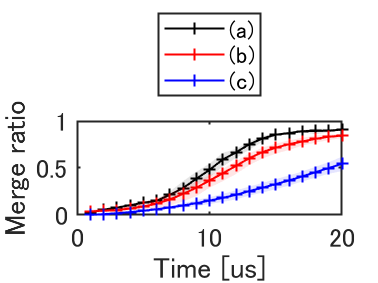



% %時間は計測時間のまま
% arange=472:482;
% brange=477:487;
% crange=482:500;
% 
% figure
% plot(arange,mean(a_wide(:,1:3),2),'k-','LineWidth',1)
% hold on
% plot(brange,mean(b_wide(:,1:3),2),'r-','LineWidth',1)
% plot(crange,mean(c_wide(:,1:2),2),'b-','LineWidth',1)
%  ar1 = area(arange,[max(a_wide(:,1:3),[],2), min(a_wide(:,1:3),[],2)-max(a_wide(:,1:3),[],2)]);
% set(ar1(1),'FaceColor','None','LineStyle','None')
% set(ar1(2),'FaceColor','k','FaceAlpha',0.2,'LineStyle','None')
%  ar2 = area(brange,[max(b_wide(:,1:3),[],2), min(b_wide(:,1:3),[],2)-max(b_wide(:,1:3),[],2)]);
% set(ar2(1),'FaceColor','None','LineStyle','None')
% set(ar2(2),'FaceColor','r','FaceAlpha',0.2,'LineStyle','None')
%  ar3 = area(crange,[max(c_wide(:,1:2),[],2), min(c_wide(:,1:2),[],2)-max(c_wide(:,1:2),[],2)]);
% set(ar3(1),'FaceColor','None','LineStyle','None')
% set(ar3(2),'FaceColor','b','FaceAlpha',0.2,'LineStyle','None')
% hold off
% ylabel('delta [m]')
% xlabel('Time [us]')
% xlim([472 500])
% legend('(a)','(b)','(c)','Location','northeast')
% ha1 = gca;
% ha1.LineWidth = 1;
% ha1.FontSize=13;

%fitrate-plot
figure
plot(arange,mean(afit(:,1:3),2),'k-+','LineWidth',1)
hold on
plot(brange,mean(bfit(:,1:3),2),'r-+','LineWidth',1)
plot(crange,mean(cfit(:,1:2),2),'b-+','LineWidth',1)
 ar1 = area(arange,[max(afit(:,1:3),[],2), min(afit(:,1:3),[],2)-max(afit(:,1:3),[],2)]);
set(ar1(1),'FaceColor','None','LineStyle','None')
set(ar1(2),'FaceColor','k','FaceAlpha',0.1,'LineStyle','None')
 ar2 = area(brange,[max(bfit(:,1:3),[],2), min(bfit(:,1:3),[],2)-max(bfit(:,1:3),[],2)]);
set(ar2(1),'FaceColor','None','LineStyle','None')
set(ar2(2),'FaceColor','r','FaceAlpha',0.1,'LineStyle','None')
 ar3 = area(crange,[max(cfit(:,1:2),[],2), min(cfit(:,1:2),[],2)-max(cfit(:,1:2),[],2)]);
set(ar3(1),'FaceColor','None','LineStyle','None')
set(ar3(2),'FaceColor','b','FaceAlpha',0.1,'LineStyle','None')
hold off
ylabel('Merge ratio')
xlabel('Time [us]')
xlim([0 20])%xlim([0 30])
ylim([0 1])
legend('(a)','(b)','(c)','Location','northoutside')
ha1 = gca;
ha1.LineWidth = 1;
ha1.FontSize=13;

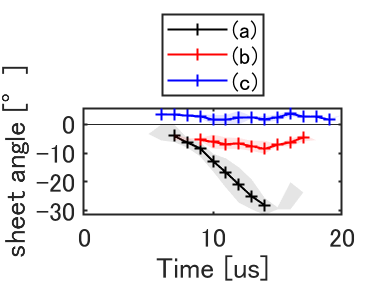

%angle-plot
figure
plot(arange,mean(aslope(:,1:3),2),'k-+','LineWidth',1)
hold on
plot(brange,mean(bslope(:,1:3),2),'r-+','LineWidth',1)
plot(crange,mean(cslope(:,1:2),2),'b-+','LineWidth',1)
 ar1 = area(arange,[max(aslope(:,1:3),[],2), min(aslope(:,1:3),[],2)-max(aslope(:,1:3),[],2)]);
set(ar1(1),'FaceColor','None','LineStyle','None')
set(ar1(2),'FaceColor','k','FaceAlpha',0.1,'LineStyle','None')
 ar2 = area(brange,[max(bslope(:,1:3),[],2), min(bslope(:,1:3),[],2)-max(bslope(:,1:3),[],2)]);
set(ar2(1),'FaceColor','None','LineStyle','None')
set(ar2(2),'FaceColor','r','FaceAlpha',0.1,'LineStyle','None')
 ar3 = area(crange,[max(cslope(:,1:2),[],2), min(cslope(:,1:2),[],2)-max(cslope(:,1:2),[],2)]);
set(ar3(1),'FaceColor','None','LineStyle','None')
set(ar3(2),'FaceColor','b','FaceAlpha',0.1,'LineStyle','None')
hold off
ylabel('sheet angle [°]')
xlabel('Time [us]')
xlim([0 20])%xlim([0 30])
ylim([-0.55 0.1].*180./pi)
legend('(a)','(b)','(c)','Location','northoutside')
ha2 = gca;
ha2.LineWidth = 1;
ha2.FontSize=13;

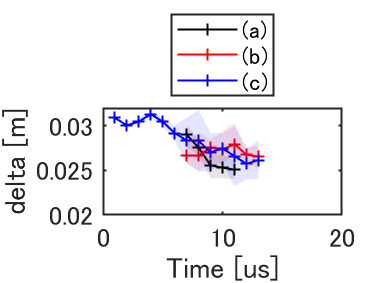

%wide-plot

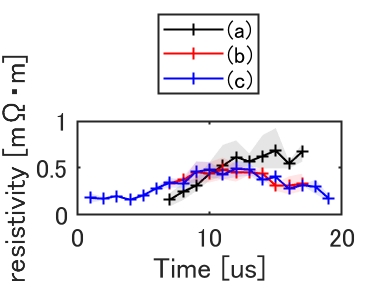

%22/10/31　下がりきるまでの時間に限定
%22/11/21 Brの肩の間の半値幅に限定（本来はBrから計算したjtの半値幅をとるためスケールを合わせた）
figure
awide=awide./2;
bwide=bwide./2;
cwide=cwide./2;

plot(arange(1:11),mean(awide(1:11,1:3),2),'k-+','LineWidth',1)
hold on
plot(brange(1:13),mean(bwide(1:13,1:3),2),'r-+','LineWidth',1)
plot(crange(1:13),mean(cwide(1:13,1:2),2),'b-+','LineWidth',1)
 ar1 = area(arange(1:11),[max(awide(1:11,1:3),[],2), min(awide(1:11,1:3),[],2)-max(awide(1:11,1:3),[],2)]);
set(ar1(1),'FaceColor','None','LineStyle','None')
set(ar1(2),'FaceColor','k','FaceAlpha',0.1,'LineStyle','None')
 ar2 = area(brange(1:13),[max(bwide(1:13,1:3),[],2), min(bwide(1:13,1:3),[],2)-max(bwide(1:13,1:3),[],2)]);
set(ar2(1),'FaceColor','None','LineStyle','None')
set(ar2(2),'FaceColor','r','FaceAlpha',0.1,'LineStyle','None')
 ar3 = area(crange(1:13),[max(cwide(1:13,1:2),[],2), min(cwide(1:13,1:2),[],2)-max(cwide(1:13,1:2),[],2)]);
set(ar3(1),'FaceColor','None','LineStyle','None')
set(ar3(2),'FaceColor','b','FaceAlpha',0.1,'LineStyle','None')
hold off
ylabel('delta [m]')
xlabel('Time [us]')
xlim([0 20])%xlim([0 30])
ylim([0.02 0.032])%ylim([0.045 0.065])%ylim([0.01 0.045])
legend('(a)','(b)','(c)','Location','northoutside')
ha1 = gca;
ha1.LineWidth = 1;
ha1.FontSize=13;
%eta-plot
figure
plot(arange,mean(aeta(:,1:3),2).*1e+3,'k-+','LineWidth',1)
hold on
plot(brange,mean(beta(:,1:3),2).*1e+3,'r-+','LineWidth',1)
plot(crange,mean(ceta(:,1:2),2).*1e+3,'b-+','LineWidth',1)
 ar1 = area(arange,[max(aeta(:,1:3),[],2).*1e+3, min(aeta(:,1:3),[],2).*1e+3-max(aeta(:,1:3),[],2).*1e+3]);
set(ar1(1),'FaceColor','None','LineStyle','None')
set(ar1(2),'FaceColor','k','FaceAlpha',0.1,'LineStyle','None')
 ar2 = area(brange,[max(beta(:,1:3),[],2).*1e+3, min(beta(:,1:3),[],2).*1e+3-max(beta(:,1:3),[],2).*1e+3]);
set(ar2(1),'FaceColor','None','LineStyle','None')
set(ar2(2),'FaceColor','r','FaceAlpha',0.1,'LineStyle','None')
 ar3 = area(crange,[max(ceta(:,1:2),[],2).*1e+3, min(ceta(:,1:2),[],2).*1e+3-max(ceta(:,1:2),[],2).*1e+3]);
set(ar3(1),'FaceColor','None','LineStyle','None')
set(ar3(2),'FaceColor','b','FaceAlpha',0.1,'LineStyle','None')
hold off
ylabel('resistivity [mΩ・m]')
xlabel('Time [us]')
xlim([0 20])%xlim([0 30])
% ylim([0.01 0.045])
legend('(a)','(b)','(c)','Location','northoutside')
ha1 = gca;
ha1.LineWidth = 1;
ha1.FontSize=13;

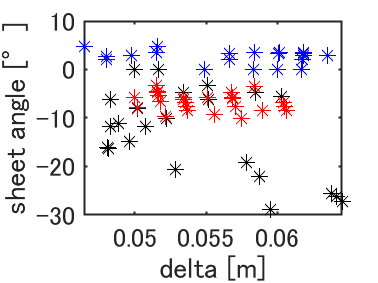



figure
plot(wide(:,1:3),slope(:,1:3),'k*','MarkerSize',8)
hold on
plot(wide(:,4:6),slope(:,4:6),'r*','MarkerSize',8)
plot(wide(:,7:8),slope(:,7:8),'b*','MarkerSize',8)
xlabel('delta [m]')
ylabel('sheet angle [°]')
ha1 = gca;
ha1.LineWidth = 1;
ha1.FontSize=13;

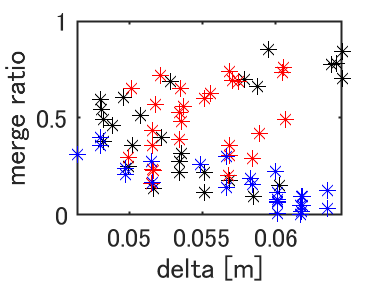


figure
plot(wide(:,1:3),fitrate(:,1:3),'k*','MarkerSize',8)
hold on
plot(wide(:,4:6),fitrate(:,4:6),'r*','MarkerSize',8)
plot(wide(:,7:8),fitrate(:,7:8),'b*','MarkerSize',8)
xlabel('delta [m]')
ylabel('merge ratio')
ha1 = gca;
ha1.LineWidth = 1;
ha1.FontSize=13;

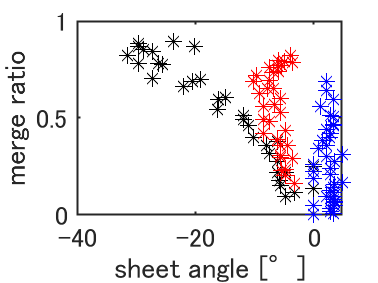


figure
plot(slope(:,1:3),fitrate(:,1:3),'k*','MarkerSize',8)
hold on
plot(slope(:,4:6),fitrate(:,4:6),'r*','MarkerSize',8)
plot(slope(:,7:8),fitrate(:,7:8),'b*','MarkerSize',8)
xlabel('sheet angle [°]')
ylabel('merge ratio')
ha1 = gca;
ha1.LineWidth = 1;
ha1.FontSize=13;

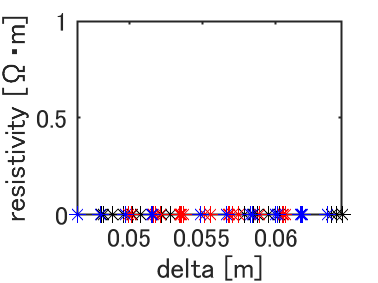


figure
plot(wide(:,1:3),xeta(:,1:3),'k*','MarkerSize',8)
hold on
plot(wide(:,4:6),xeta(:,4:6),'r*','MarkerSize',8)
plot(wide(:,7:8),xeta(:,7:8),'b*','MarkerSize',8)
xlabel('delta [m]')
ylabel('resistivity [Ω・m]')
ylim([0 1])
ha1 = gca;
ha1.LineWidth = 1;
ha1.FontSize=13;

function [fitrate, merge_ind] = fitratecalc(T, IDX, pathname,start,frame)
date=T.date(IDX);
shot=T.shot(IDX);
TF_shot=T.TFoffset(IDX);
d_tacq=T.d_tacq(IDX);
d_tacqTF=T.TFdtacq(IDX);
offset_TF=isfinite(TF_shot);
Cr=T.Crowbar_us_(IDX);
if isnan(Cr)
    Cr=num2str('-');
end
CB=T.CB1_kV_(IDX);
%start=T.Period_StartTime_(IDX);
if isnan(T.EF_A_(IDX))
    i_EF=150;
else  
    i_EF=T.EF_A_(IDX);
end
% %rgwデータの読み込み->coil current plot用
% filepath.rgw=strcat(pathname.ts3u, '/', string(date),'/' ...
%     ,string(date),num2str(shot,'%03i'),'.rgw');
% 
% if exist(filepath.rgw)~=0
% rgwdata = importfile(filepath.rgw);
% rgwdata.ch6=rgwdata.ch6*(65.7146)*12;
% rgwdata.ch7=rgwdata.ch7*(-57.6030)*3;
% rgwdata.ch8=rgwdata.ch8*(-187.170)*3-50;
% %各ショットのTF,PF1,PF2のcoil current
% plot(repmat([0:0.1:0.1*10000],3,1)',rgwdata{2:end,:})
% legend('TF','PF1','PF2')
% ylabel('coil current [kA]')
% ylim([-250 150])
% xlim([300 550])
% title(strcat('IDX',num2str(IDX),': Cr',num2str(T.Crowbar_us_(IDX))))
% hold off
% end

[B_z,r_probe,z_probe,ch_dist,data,data_raw,shot_num]= get_B_z(date,TF_shot,shot,offset_TF,i_EF,pathname.ts3u);
B_z = B_z([2,3,4,6,7,8],2:end,:);
data = data([2,3,4,6,7,8],2:end,:);
z_probe = z_probe(2:end);
ch_dist = ch_dist([2,3,4,6,7,8],2:end);
r_probe = r_probe([2,3,4,6,7,8]);

mesh_z=100;
mesh_r=100;

z_space = linspace(z_probe(1),z_probe(end),mesh_z);
r_space = linspace(r_probe(1),r_probe(end),mesh_r);
[psi_mesh_z,psi_mesh_r] = meshgrid(z_space,r_space);
for i=1:frame
    psi  = get_psi(B_z,r_probe,i+start);
    psi_store(:,:,i)= griddata(z_probe,r_probe,psi,psi_mesh_z,psi_mesh_r,'cubic');
end

[max_psi,max_psi_r]=max(psi_store,[],1); %各時間、各列(z)ごとのpsiの最大値
max_psi=squeeze(max_psi);
psi_pr=zeros(3,frame);
%plot(max_psi)
for i=1:frame
    r_ind=max_psi_r(:,:,i);
    max_psi_ind=find(islocalmax(smooth(max_psi(:,i)),'MaxNumExtrema', 2));
    if numel(max_psi(min(max_psi_ind),i))==0
    psi_pr(1,i)=NaN;
    else
    psi_pr(1,i)=max_psi(min(max_psi_ind),i);
    end
    if numel(max_psi(max(max_psi_ind),i))==0
    psi_pr(2,i)=NaN;
    else
    psi_pr(2,i)=max_psi(max(max_psi_ind),i);
    end
    if numel(find(islocalmin(smooth(max_psi(:,i)),'MaxNumExtrema', 1)))==0
        psi_pr(3,i)=NaN;
    else
        min_psi_ind=islocalmin(smooth(max_psi(:,i)),'MaxNumExtrema', 1);
        xr=r_ind(min_psi_ind);
        if xr==1 || xr==mesh_r %r両端の場合は検知しない
            psi_pr(3,i)=NaN;
        else
        psi_pr(3,i)=max_psi(min_psi_ind,i);
        end
    end
    if max_psi(1,i)==max(max_psi(1:end/2,i))
        psi_pr(1,i)=NaN; %max_psi(1,i);
    end    
    if max_psi(end,i)==max(max_psi(end/2:end,i))
        psi_pr(2,i)=NaN; %max_psi(end,i);
    end
end
fitrate=psi_pr(3,:)./min(psi_pr(1:2,:),[],1);
merge_ind=find(fitrate>=0,1); %fitrateが初めて0以上となる点のindex
% %合体率のplot
% figure('Position',[700,350,350,300])
% plot(repmat([1:frame]+start,3,1)',psi_pr','--o')
% ylabel('Psi [Wb]')
% xlabel('Time [us]')
% ylim([0 inf])
% legend('Psi_{private1}','Psi_{private2}','Psi_{common}')
% title(strcat('IDX',num2str(IDX),', Cr',num2str(Cr),' us, CB',num2str(CB),' kV'))
% title(strcat('IDX',num2str(IDX),' CB:',num2str(T.CB1_kV_),' kV, Cr:',num2str(T.Crowbar_us_),' us'))
end

function p=cal_diff(T, IDX, pathname, tstart, tend,start,frame)
date=T.date(IDX);
if isnan(T.EF_A_(IDX))%%NaNでないことを確認（ログが空白だとNaNになる）
    i_EF=150;
else  %NaNなら150をとりあえず代入、記入されているときはその値を使う
    i_EF=T.EF_A_(IDX);
end
d_tacq=T.d_tacq(IDX);
d_tacqTF=T.TFdtacq(IDX);
n=50; %rz方向のメッシュ数

%trange = tstart:tend+1;
%tsize = tend-tstart+1;
tsize=frame;
trange=[1:frame]+start;

[grid2D, data2D] = pcbdata(date, d_tacq, d_tacqTF, trange, [], n,i_EF);

if isstruct(grid2D)==0 %もしdtacqデータがない場合次のloopへ(データがない場合NaNを返しているため)
    return
end

%%%midplaneとかO点、X点を探す
[psimid,mid]=min(data2D.psi,[],2);
[opoint,~]=islocalmin(psimid,1);
[xpoint,~]=islocalmax(psimid,1);
% [xp_psi,maxxp]=max(squeeze(psimid),[],1);
r_index=1:n;

%X点での勾配
p=zeros(2,tsize);

for i=1:tsize
    if sum(xpoint(:,:,i))>0   
        r_xind=r_index(xpoint(:,:,i));
        z_xind=mid(xpoint(:,:,i),:,i);
        if numel(r_xind)>1
            [~,I]=max(psimid(r_xind));
            r_xind=r_xind(I);
            z_xind=z_xind(I);
        end
        
        r_s=max(2,r_xind-5);
        r_n=min(n,r_xind+5);
        p(:,i)=polyfit(grid2D.rq(r_s:r_n,1),grid2D.zq(1,squeeze(mid(r_s:r_n,:,i))),1);

        if z_xind==1 || z_xind==n
            p(:,i)=NaN;
        end
    else
        p(:,i)=NaN;
    end   
end


% figure
% plot(tstart:tend,p(1,:),'ko-')
% xlim([tstart tend])
% xlabel('Time [us]')
% ylabel('current sheet slope')
% ylim([-0.55 0.1])
% ha3 = gca;
% ha3.LineWidth = 1;
% ha3.FontSize=13;
% Cr=T.Crowbar_us_(IDX);
% if isnan(Cr)
%     Cr=num2str('-');
% end
% CB=T.CB1_kV_(IDX);
% sgtitle(strcat('IDX',num2str(IDX),', Cr',num2str(Cr),' us, CB',num2str(CB),' kV'),'FontSize',12)
end